# **Problem E9.9**


$$F\left(x\right)={\left(1+x_1 +x_2 \right)}^2 +\frac{1}{4}x_1^4$$


## i. Second Order Taylor Expansion at [2; 2]


$$\hat{\;F_2 \left(x\right)} =F\left(x_0 \right)+\nabla {F\left(x\right)}_{x=x_0 }^T \left(x-x_0 \right)+\frac{1}{2}{\left(x-x_0 \right)}^T \nabla^2 {F\left(x\right)}_{x=x_0 } \left(x-x_0 \right)\;$$


In order to calculate this first we need to calculate the Gradient and Hessian of $F\left(x\right)$:


$$\begin{array}{l}
\nabla F\left(x\right)=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x_1 }F\left(x\right)\\
\frac{\partial }{\partial x_2 }F\left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\left(1+x_1 +x_2 \right)+x_1^3 \\
2\left(1+x_1 +x_2 \right)
\end{array}\right\rbrack \\
\nabla^2 F\left(x\right)=\left\lbrack \begin{array}{cc}
\frac{\partial {\;}^2 }{\partial \;x_1^2 }F\left(x\right) & \frac{\partial {\;}^2 }{\partial \;x_1 \partial \;x_2 }F\left(x\right)\\
\frac{\partial {\;}^2 }{\partial \;x_2 \partial \;x_1 }F\left(x\right) & \frac{\partial {\;}^2 }{\partial \;x_2^2 }F\left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
2+3x_1^2  & 2\\
2 & 2
\end{array}\right\rbrack 
\end{array}$$


We will substitute for $x_0$ to calculate all of the necessary components for $\hat{\;F_2 \left(x\right)}$.


$$F\left(x_0 \right)=29,\nabla {F\left(x\right)}_{x=x_0 }^T =\left\lbrack \begin{array}{c}
18\\
10
\end{array}\right\rbrack ,\nabla^2 {F\left(x\right)}_{x=x_0 } =\left\lbrack \begin{array}{cc}
14 & 2\\
2 & 2
\end{array}\right\rbrack$$


Finally we can calculate the approximation:


$$\;\hat{\;\;F_2 \left(x\right)} =29+\left\lbrack \begin{array}{cc}
18 & 10
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 -2\\
x_2 -2
\end{array}\right\rbrack +\frac{1}{2}\left\lbrack \begin{array}{cc}
x_1 -2 & x_2 -2
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
14 & 2\\
2 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 -2\\
x_2 -2
\end{array}\right\rbrack =7x_1^2 +2x_1 x_2 -14x_1 +x_2^2 +2x_2 +13$$


## ii. Contour Plot of the Approximation

We will perform the calculations by hand but plot the contour using MATLAB.

First we will find the Stationary Points of $\hat{\;F_2 \left(x\right)}$:


$$\nabla \hat{\;F_2 \left(x\right)} =0\to \left\lbrack \begin{array}{c}
14x_1 +2x_2 -14\\
2x_1 +2x_2 +2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \to \left\lbrace \begin{array}{ll}
14x_1 +2x_2 -14=0 & \\
2x_1 +2x_2 +2=0 & 
\end{array}\right.\to X=\left\lbrack \begin{array}{c}
\frac{4}{3}\\
-\frac{7}{3}
\end{array}\right\rbrack$$


We will now determine the type of this Stationary Point using the Hessian of $\hat{\;F_2 \left(x\right)}$:


$$\nabla^2 \hat{\;F_2 \left(x\right)} =\left\lbrack \begin{array}{cc}
14 & 2\\
2 & 2
\end{array}\right\rbrack ,\textrm{eig}\left(\nabla^2 \hat{\;F_2 \left(x\right)} \right)=\left\lbrack \begin{array}{c}
8-2\sqrt{\;10}\\
2\sqrt{\;10}+8
\end{array}\right\rbrack >\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


Since $\lambda_1$ and $\lambda_2$ are both positive the Hessian is positive-definite and therefore the Stationary Point is a strong minimum. 

We expect the contour plot to look like concentric ellipsoids (because $\lambda_1 \not= \lambda_2$).

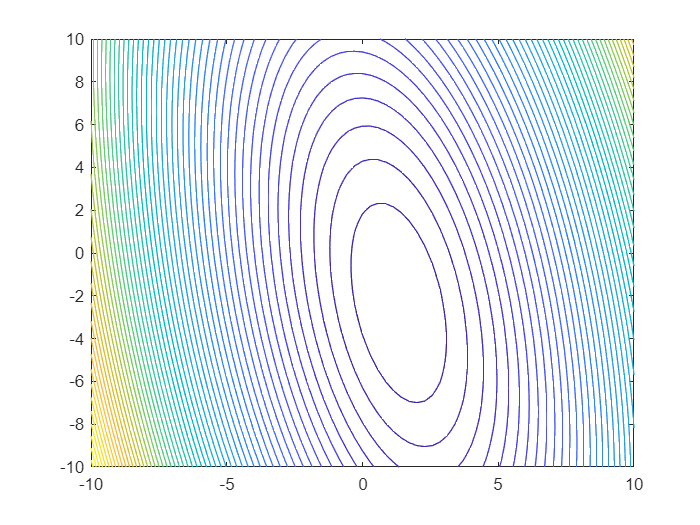

syms x1 x2 real
X = [x1; x2];
f_hat = 7*x1^2 + 2*x1*x2 - 14*x1 + x2^2 + 2*x2 + 13;
fcontour(f_hat, [-10, 10, -10, 10], 'LevelStep', 20)

This confirms our suspicion.

## iii. One Iteration of Newton's Method

According to Newton's method:


$$x_{k+1} =x_k -A_k^{-1} g_k$$


We know that $x_0 =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack$and $A_1 =$${\left\lbrack \begin{array}{cc}
2+3x_1^2  & 2\\
2 & 2
\end{array}\right\rbrack }_{x=x_0 } =\left\lbrack \begin{array}{cc}
14 & 2\\
2 & 2
\end{array}\right\rbrack$.

Additionally we know that $g_k =\nabla {F\left(x\right)}_{x\;={\;x}_k } =\left\lbrack \begin{array}{c}
18\\
10
\end{array}\right\rbrack$. Finally we can perform the first step:


$$x_1 =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
\frac{1}{12} & -\frac{1}{12}\\
-\frac{1}{12} & -\frac{7}{12}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
18\\
10
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{4}{3}\\
-\frac{7}{3}
\end{array}\right\rbrack$$


As we can see, Newton's method converges to the stationary point of the second order Taylor expansion in one iteration.

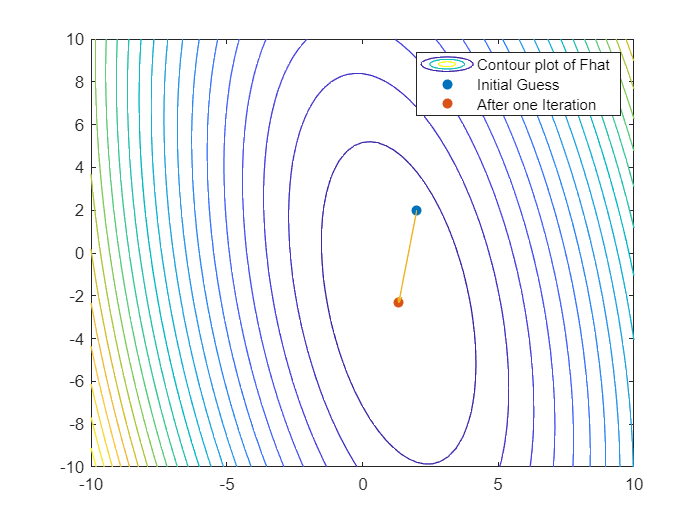

fcontour(f_hat, [-10, 10, -10, 10], 'LevelStep', 50)
hold on;
scatter(2, 2, 'filled');
hold on;
scatter(4/3, -7/3, 'filled');
hold on;
quiver(2, 2, -2+4/3, -2-7/3, 0);
legend('Contour plot of Fhat', 'Initial Guess', 'After one Iteration');
hold off;

## iv.

As proven in part (ii), $x_1$ obtained from one iteration of the Newton's Method is indeed the Stationary Point of $\hat{\;F}$and that Stationary Point was analyzed to be a strong minimum as well. 

In order to check if this point is also a minimum for the original function, we recall that:


$$\begin{array}{l}
\nabla F\left(x\right)=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial x_1 }F\left(x\right)\\
\frac{\partial }{\partial x_2 }F\left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\left(1+x_1 +x_2 \right)+x_1^3 \\
2\left(1+x_1 +x_2 \right)
\end{array}\right\rbrack \\
\nabla^2 F\left(x\right)=\left\lbrack \begin{array}{cc}
\frac{\partial {\;}^2 }{\partial \;x_1^2 }F\left(x\right) & \frac{\partial {\;}^2 }{\partial \;x_1 \partial \;x_2 }F\left(x\right)\\
\frac{\partial {\;}^2 }{\partial \;x_2 \partial \;x_1 }F\left(x\right) & \frac{\partial {\;}^2 }{\partial \;x_2^2 }F\left(x\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
2+3x_1^2  & 2\\
2 & 2
\end{array}\right\rbrack 
\end{array}$$


Substituting $x_1 =$$\left\lbrack \begin{array}{c}
\frac{4}{3}\\
-\frac{7}{3}
\end{array}\right\rbrack$in the gradient:


$$\nabla {F\left(x\right)}_{x=x_1 } =\left\lbrack \begin{array}{c}
\frac{64}{27}\\
0
\end{array}\right\rbrack \not= \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


Therefore $x_1$is not a Stationary Point of $F$and hence it also cannot be its strong minimum.

## v.

Newton's method will always converge to a Stationary Point after one iteration on a quadratic function, whether that point is a minimum, maximum or a saddle point. However, it can have unpredictable results when used on higher degree functions as convergence depends on the initial guess and the surface of the function itself. Different initial guesses can lead to different convergences because they will have different second order Taylor expansions.